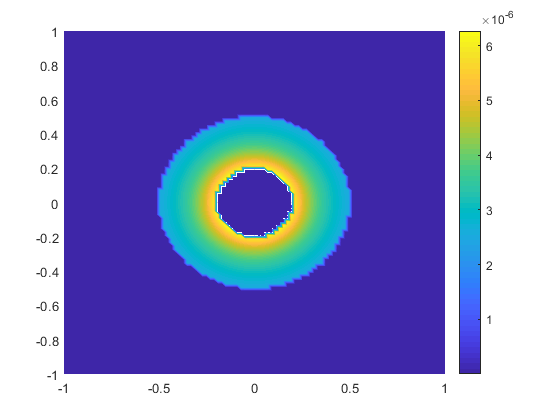


mu_0 = 1.257e-6;
J = 10e-3;
R = 0.2;
R_core = 0.5;
n_p = 100;
mu = mu_0 * 5000;

x = linspace(-1,1,n_p);
y = linspace(-1,1,n_p);
[X,Y] = meshgrid(x,y);
B = zeros(size(X));

r = sqrt(X.^2 + Y.^2) <= R_core;
B(~r) = (mu_0*J*R^2)./(2*(sqrt(X(~r).^2 + Y(~r).^2)));
r_I = sqrt(X.^2 + Y.^2) <= R;
B(r_I) = (mu_0*J*(sqrt(X(r_I).^2 + Y(r_I).^2)))./2;
r = r & ~r_I;
B(r) = (mu*J*R^2)./(2*(sqrt(X(r).^2 + Y(r).^2)));

figure
surf(X,Y,B)
colorbar
shading interp
view(2)
print('B_iron_core', '-dpng')

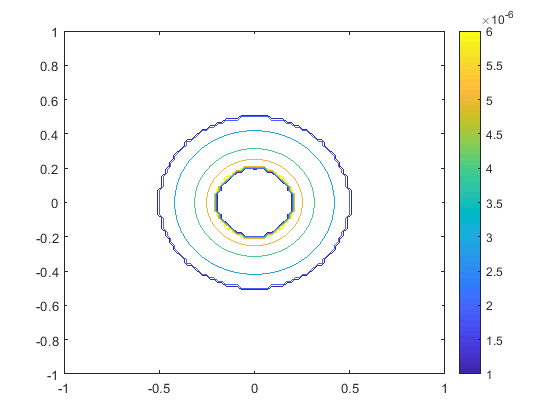


figure
contour(X,Y,B)
colorbar